`Daniel Park and Elias Wheatfall`

# **Gauntlet Challenge Quiver Plot and Calculating Distance**

**Code contains all of our calculations and plots (except for the LIDAR plot).**

The LIDAR plot can be obtained by running `park_wheatfall_gauntlet_drive.m`

## Quiver Plot

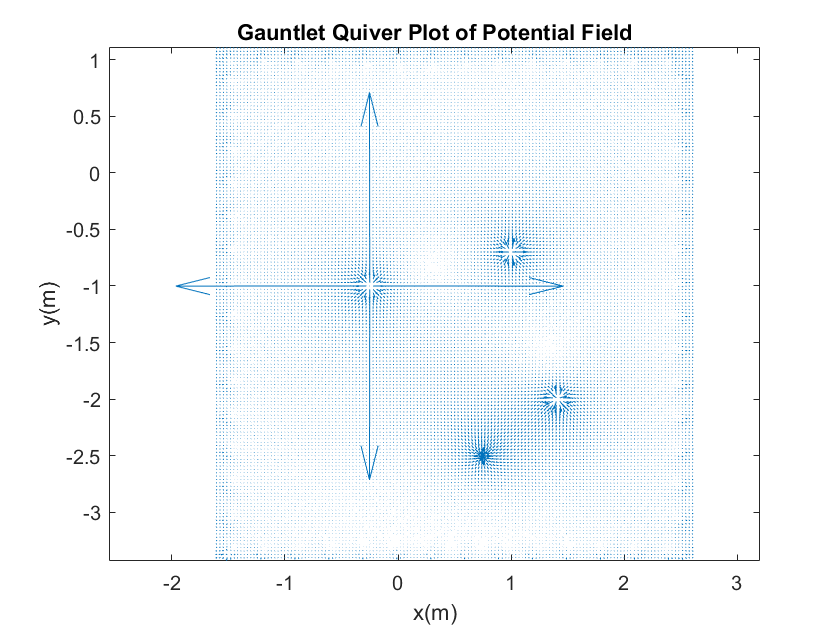

% Initialize all the scaling variables for the drive
syms x y
clf
scale = 5;
wall_scale = .5;
% Make the grid that the quiver plot will be on
[x,y] = meshgrid(-1.6:0.03:2.6,-3.4:0.03:1.1);

% Make the gradient equation for the obstacles and barrel of benevolence
eq = scale*-log(sqrt((x-1.41).^2 + (y+2).^2)) ...
    - scale*log(sqrt((x - 1).^2 + (y+.7).^2)) ...
    - scale*log(sqrt((x + .25).^2 + (y+1).^2)) ...
    + 6*log(sqrt((x -.75).^2 + (y+2.5).^2));

% Instance of the wall
wall = 0.3;

% x-axis walls on y = -1.5, 2.5
for a = -1.5:wall:2.5
    eq = eq - wall_scale*log(sqrt((x-a).^2 + (y+3.37).^2)) - wall_scale*log(sqrt((x-a).^2 + (y-1).^2));
end

% y-axis walls on y = -3.37, 1
for b = -3.37:wall:1
    eq = eq - wall_scale* log(sqrt((x+1.5).^2 + (y-b).^2)) - wall_scale*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% Plot the quiver diagram
[U,V] = gradient(eq);
h1 = quiver(x,y,-U,-V);
set(h1,'AutoScale','on', 'AutoScaleFactor', 40)
title("Gauntlet Quiver Plot of Potential Field")
xlabel("x(m)")
ylabel("y(m)")
axis equal

## Calculating Distance

%% Import the travel dataset csv file and put them in variables
gauntlet_travel = csvread('gauntlet_travel_dataset.csv',3);
% The elapsed time for each encoder value going up
timeseconds = gauntlet_travel((1:end),1);
% The left encoder values
encoderLeftmeters = gauntlet_travel((1:end),2);
% The right encoder values
encoderRightmeters = gauntlet_travel((1:end),3);

% Reinstate the time to start at 0
timeseconds = timeseconds - min(timeseconds);

% Calculate the left and right wheel velocities
left_wheel_vel = encoderLeftmeters./timeseconds;
right_wheel_vel = encoderRightmeters./timeseconds;

% Calculate the total Neato velocity
velocity = (left_wheel_vel + right_wheel_vel) ./ 2;

% Calculate the distance from the velocity and the elapsed time
distance = velocity.*timeseconds;

% Get the largest value in distance to show the total distance traveled by
% our Neato
total_measured_distance_traveled = max(distance)

total_measured_distance_traveled = 3.7957

% Calculate the optimal distance from the starting point of the Neato to
% the Barrel of Benevolence
positions = [0,0 ; 0.75,-2.5];
optimal_distance = pdist(positions,'euclidean')

optimal_distance = 2.6101

## Calculate the Intended Path

%% Initialize all the scaling variables for the drive
syms x y r phi d Xn Yn
clf
scale = .1;
wall_scale = 1;

%% Make the gradient equation for the obstacles and barrel of benevolence
eq = scale*-log(sqrt((x-1.41).^2 + (y+2).^2)) ...
    - scale*log(sqrt((x - 1).^2 + (y+.7).^2)) ...
    - scale*log(sqrt((x + .25).^2 + (y+1).^2)) ...
    + 3*log(sqrt((x -.75).^2 + (y+2.5).^2));

%% Plot the walls
% Instance of the wall
wall = 0.3;

% x-axis walls on y = -1.5, 2.5
for a = -1.5:wall:2.5
    eq = eq - wall_scale*log(sqrt((x-a).^2 + (y+3.37).^2)) - wall_scale*log(sqrt((x-a).^2 + (y-1).^2));
end

% y-axis walls on y = -3.37, 1
for b = -3.37:wall:1
    eq = eq - wall_scale* log(sqrt((x+1.5).^2 + (y-b).^2)) - wall_scale*log(sqrt((x-2.5).^2 + (y-b).^2));
end

%% Draw the Neato path driven using the equation

%Starting parameters
start_position=[0,0];
base_equation = eq;
lamda  =  0.2;
delta = 0.9;
r = 0.235/2; %Radius between two wheels
speed = .2;

%Store gradient equation and second position
gradient_equation = [-1.*diff(base_equation,x);-1.*diff(base_equation,y)];
next_position = (lamda .* double(subs(gradient_equation,[x,y],[start_position])))' + start_position;
start_angle = deg2rad(350);
%Create array of position values
positions = [start_position];
angles = [start_angle];

% Get all the Neato positions over time
while double(norm(lamda.* subs(gradient_equation,[x,y],[next_position]))') >.1
    %Append positions to a list
    positions = [positions;next_position];
    
    %Calculate angle transitions
    next_angle = atan2(abs(double(subs(gradient_equation(2,:),[x,y],[next_position]))),abs(double(subs(gradient_equation(1,:),[x,y],[next_position]))));
    angles = [angles;next_angle];
    
    %Calculate next position
    next_position = (lamda .* double(subs(gradient_equation,[x,y],[next_position])))' + next_position;
    lamda  = lamda * delta;
end

## **Calculate the Measured Path**

% Get the data from the travel dataset we collected using 'collectScans.m'
% using Docker
M = readmatrix("gauntlet_travel_dataset.csv");

% Import the time seconds and encoder values
timeseconds = M(:,1);
encoderLeftmeters = M(:,2);
encoderRightmeters = M(:,3);

% Manipulate the time seconds variable to have the time start at 0 seconds
timeseconds = timeseconds - min(timeseconds);

% Diameter of the wheel (in meters)
d = 0.235; %m

% Calculate the left and right wheel velocities
left_wheel_vel = diff(encoderLeftmeters)./diff(timeseconds);
right_wheel_vel = diff(encoderRightmeters)./diff(timeseconds);

% Calculate the velocity of the Neato
velocity = (left_wheel_vel + right_wheel_vel) / 2 ;
omega  = (right_wheel_vel - left_wheel_vel) / d ;

% Create the measured position matrix to start the x and y encoder values
measured_position = zeros(length(velocity)+1,3);

% Get the positions into the measured position
dt = diff(timeseconds);
for i = 1:length(velocity)
    theta = measured_position(i,3) + omega(i)*dt(i);
    rx = measured_position(i,1) + velocity(i) * cos(theta+pi/3) * dt(i);
    ry = measured_position(i,2) + velocity(i) * sin(theta+pi/3) * dt(i);
    measured_position(i+1,:) = [rx ry theta];
end

% Turn the measured position by 45 degrees to match the direction of the
% intended path
turn = 45;
measured_position = measured_position * [cos(turn),-sin(turn),0;sin(turn),cos(turn),0;0,0,1];

## **Plot the Intended and Measured Paths on the Same Plot**

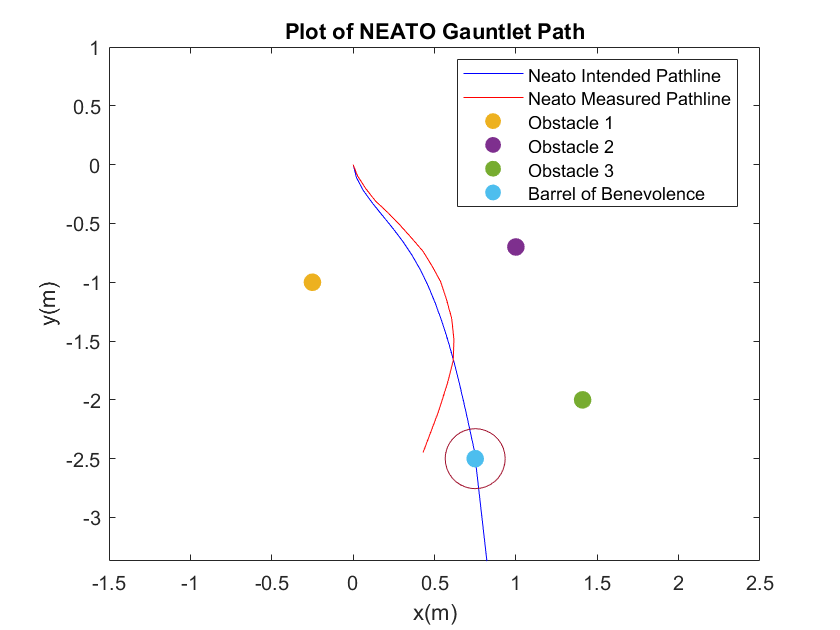

% Create a figure
figure
clf;

% Plot the intended path
plot(positions(:,1),positions(:,2),'b')
hold on

% Plot the measured path
plot(measured_position(:,1),measured_position(:,2),'r');

% Set the x and y limits of the graph to the Gauntlet walls
xlim([-1.5 2.5])
ylim([-3.37 1])

% Plot the obstacles and BoB
plot(-0.25,-1,".",'MarkerSize', 30)
plot(1,-0.7,".",'MarkerSize', 30)
plot(1.41,-2,".",'MarkerSize', 30)
plot(0.75,-2.5,".",'MarkerSize', 30)
plot(0.75,-2.5,"o",'MarkerSize', 30)

% Add title, labels, and legend to the plot
title("Plot of NEATO Gauntlet Path")
ylabel("y(m)")
xlabel("x(m)")
legend("Neato Intended Pathline", "Neato Measured Pathline", "Obstacle 1","Obstacle 2","Obstacle 3","Barrel of Benevolence","Location","best")

## **Potential Field Plot**

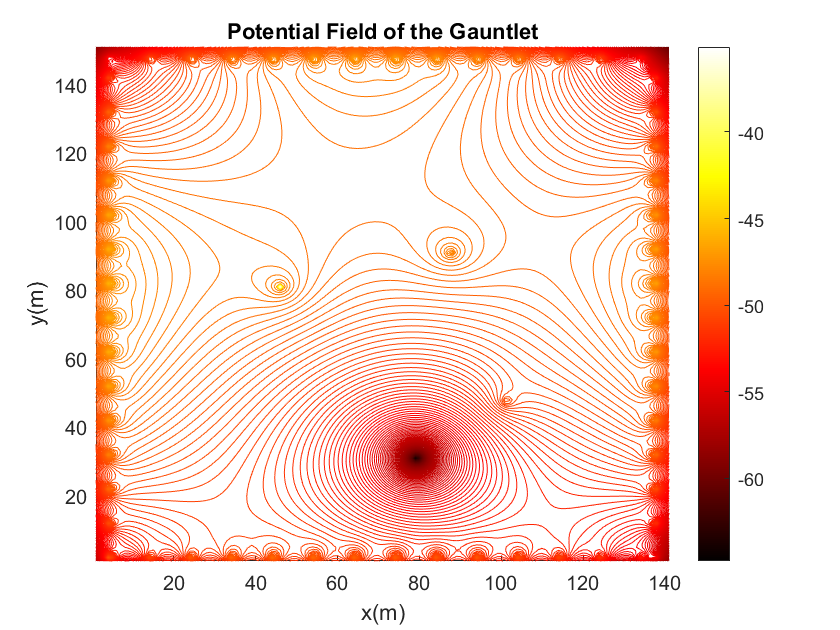

% Initialize all the scaling variables for the drive
syms x y
clf
scale = .4;
wall_scale = 1;

% Create the grid
[x,y] = meshgrid(-1.6:0.03:2.6,-3.4:0.03:1.1);
eq = scale*-log(sqrt((x-1.41).^2 + (y+2).^2)) ...
    - scale*log(sqrt((x - 1).^2 + (y+.7).^2)) ...
    - scale*log(sqrt((x + .25).^2 + (y+1).^2)) ...
    + 3*log(sqrt((x -.75).^2 + (y+2.5).^2));

% Instance of the wall
wall = 0.3;

% x-axis walls on y = -1.5, 2.5
for a = -1.5:wall:2.5
    eq = eq - wall_scale*log(sqrt((x-a).^2 + (y+3.37).^2)) - wall_scale*log(sqrt((x-a).^2 + (y-1).^2));
end

% y-axis walls on y = -3.37, 1
for b = -3.37:wall:1
    eq = eq - wall_scale* log(sqrt((x+1.5).^2 + (y-b).^2)) - wall_scale*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% Create the color map
colormap("hot")

% Label 
xlabel("x(m)")
ylabel("y(m)")
title("Potential Field of the Gauntlet")

% Create a colorbar for the potential field
colorbar

hold on
% Create the contours of the potential field
contour(eq,200)

## **Gauntlet Surface Plot**

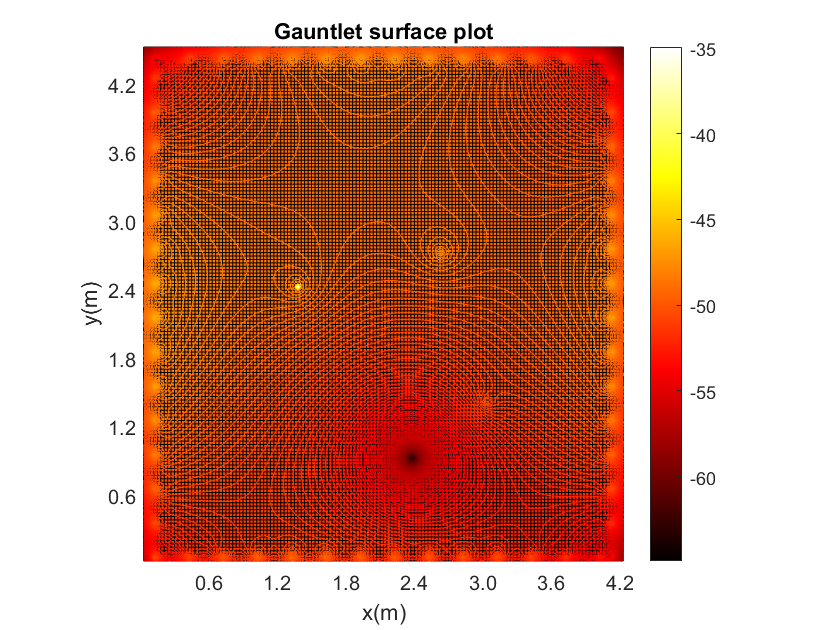

% Create a surface plot
surf(eq)

% Create tick labels for the plot
xticklabels({'0.6','1.2','1.8','2.4','3.0','3.6','4.2'})
yticklabels({'0.6','1.2','1.8','2.4','3.0','3.6','4.2'})

% Label the plot
xlabel("x(m)")
ylabel("y(m)")
zlabel("z(m)")
title("Gauntlet surface plot")
axis equal